# Dataset Information

Data set downloaded from "https://archive.ics.uci.edu/dataset/849/power+consumption+of+tetouan+city" contains 9 columns (DateTime, Temperature, Humidity, Wind Speed, general diffuse flows, diffuse flows, Zone 1 Power Consumption, Zone 2 Power Consumption, Zone 3 Power Consumption). 

The power consumption data was recorded for Quads(Zone 1), Boussafou(Zone 2) and Smir(Zone 3) distribution networks of Tetouan, Morocco. The data was collected every 10 minutes for the period between 2017-01-01: 00:00:00 and 2017-12-30: 23:50:00. The important thing to note here is that the dataset does not have any missing values.

**Note:- Information specifying Units for dataset was not found.  **

# Datetime Correction(Messy Format)

The time data in the source file is in different formats. For this reason, MATLAB is not effectively able to import it into datetime datatype. The following section recreates those values based on the selected intervals for the durations.

Start_time = datetime(2017,1,1,0,0,0);
End_time = datetime(2017,1,31,23,50,0);
Date_time = (Start_time:minutes(10):End_time)';
TetuanCitypowerconsumption = removevars(TetuanCitypowerconsumptionJanuary,"DateTime");
TetuanCitypowerconsumption = addvars(TetuanCitypowerconsumption,Date_time,'NewVariableNames',"DateTime", 'Before',"Temperature" );

# Reducing the Amount of Data

- **n** consecutive values are combined into a single value i.e., average of n consecutive entries

- This is being done to help in subsequent steps which simulate data with missing values and outliers.

mean_power_consumption = TetuanCitypowerconsumption(1,:);
mean_calculation_interval = 12; %% n consecutive values will be combined into a single value i.e., average of n consecutive entries  
size_of_source = size(TetuanCitypowerconsumption);
number_of_entries_in_source = size_of_source(1);
for i=1:mean_calculation_interval:number_of_entries_in_source
    mean_power_consumption = [mean_power_consumption ; mean(TetuanCitypowerconsumption(i:i+mean_calculation_interval-1,:))];
end
mean_power_consumption=mean_power_consumption(2:end,:);
number_of_entries_in_mean_power_consumption = number_of_entries_in_source/mean_calculation_interval;

#### X-axis label configuration for subsequent plotting

xticklabel_char_array = mean_power_consumption.DateTime(round(linspace(1,number_of_entries_in_mean_power_consumption,5)));
xticklabel_char_array.Format="MMM d";

#### Plotting Original Clean Data of Zone 1 Power Consumption

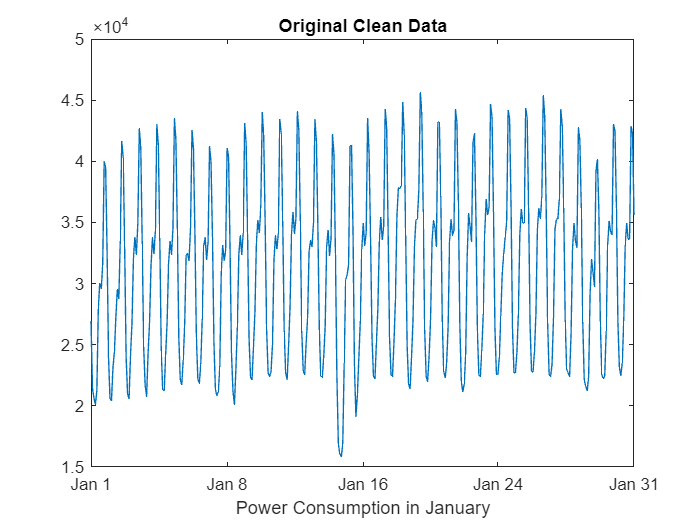

plot(mean_power_consumption.DateTime, mean_power_consumption.Zone1PowerConsumption)
xticks(xticklabel_char_array)
xticklabels(char(xticklabel_char_array))
xlabel("Power Consumption in January")
title("Original Clean Data")
xlim tight

# Making the Data Dirty

#### Creating Missing Values

no_of_missing_values=20;
consumption_data_being_processed = mean_power_consumption;
remove= 1 + (number_of_entries_in_mean_power_consumption-1).*rand(no_of_missing_values,1);
consumption_data_being_processed.Zone1PowerConsumption(round(remove)) = NaN; 

#### Creating Outliers

no_of_outlier_values = 20;
outlier_deviation_from_original_value = 0.5;

outliers_locations=round(1 + (number_of_entries_in_mean_power_consumption-1).*rand(no_of_outlier_values,1));
consumption_data_being_processed.Zone1PowerConsumption(outliers_locations) = consumption_data_being_processed.Zone1PowerConsumption(outliers_locations)+(consumption_data_being_processed.Zone1PowerConsumption(outliers_locations).*((round(-1 + ((1+1).*rand(no_of_outlier_values,1))))*(outlier_deviation_from_original_value)));

#### Plotting the Dirty Data

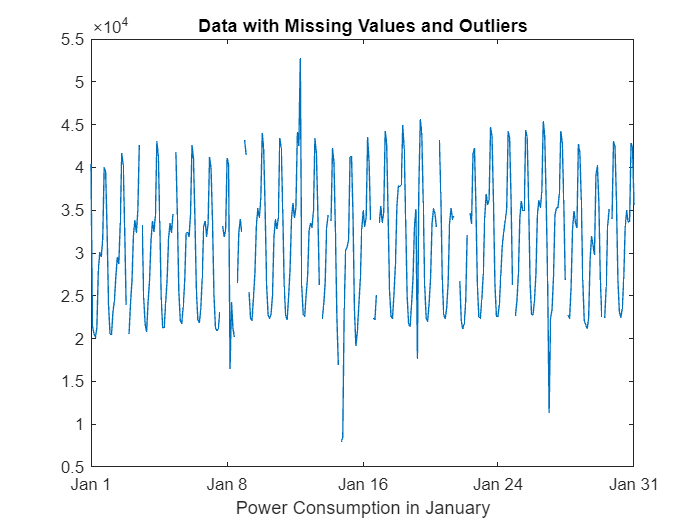

%% Missing value cleaning and plotting

plot(consumption_data_being_processed.DateTime, consumption_data_being_processed.Zone1PowerConsumption)
xticks(xticklabel_char_array)
xticklabels(char(xticklabel_char_array))
xlabel("Power Consumption in January")
title("Data with Missing Values and Outliers")
xlim tight

# Cleaning the Data

#### Filling missing values

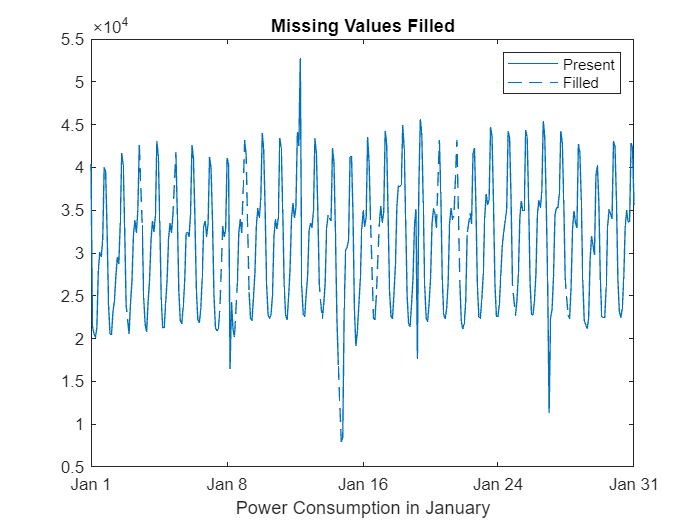

plot(consumption_data_being_processed.DateTime, consumption_data_being_processed.Zone1PowerConsumption,"-")
xticks(xticklabel_char_array)
xticklabels(char(xticklabel_char_array))
xlabel("Power Consumption in January")
title("Missing Values Filled")
xlim tight

% Fill missing values
consumption_data_being_processed.Zone1PowerConsumption = fillmissing(consumption_data_being_processed.Zone1PowerConsumption,"linear");

hold on
plot(consumption_data_being_processed.DateTime,consumption_data_being_processed.Zone1PowerConsumption,"--",Color="#0072BD")
legend("Present", "Filled")
hold off

#### Cleaning outliers

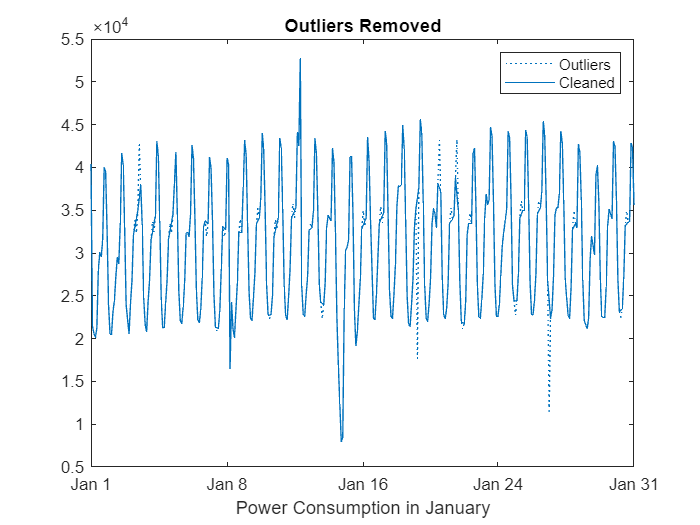

plot(consumption_data_being_processed.DateTime, consumption_data_being_processed.Zone1PowerConsumption,":")
xticks(xticklabel_char_array)
xticklabels(char(xticklabel_char_array))
xlabel("Power Consumption in January")
title("Outliers Removed")
xlim tight

% Clean outliers
consumption_data_being_processed = filloutliers(consumption_data_being_processed,"linear","movmean",3,"ThresholdFactor",1,"DataVariables","Zone1PowerConsumption");
hold on
plot(consumption_data_being_processed.DateTime,consumption_data_being_processed.Zone1PowerConsumption,"-",Color="#0072BD");
legend("Outliers", "Cleaned")
hold off

#### Plotting cleaned data along with original data

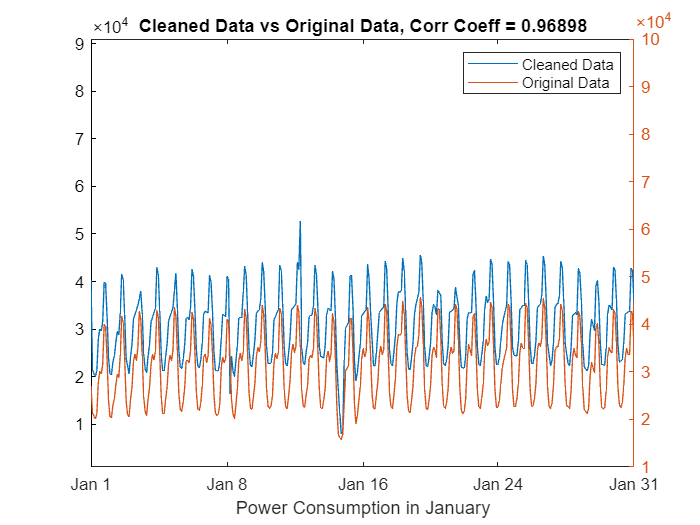

plot(consumption_data_being_processed.DateTime,consumption_data_being_processed.Zone1PowerConsumption,"-")
ylim([0.1e+4 9.1e+4])
hold on
yyaxis right
ylim([1e+4 10e+4])

plot(mean_power_consumption.DateTime, mean_power_consumption.Zone1PowerConsumption)
xticks(xticklabel_char_array)
xticklabels(char(xticklabel_char_array))
correlation_coefficient = corrcoef(consumption_data_being_processed.Zone1PowerConsumption,mean_power_consumption.Zone1PowerConsumption);
xlabel("Power Consumption in January")
title("Cleaned Data vs Original Data, Corr Coeff = "+correlation_coefficient(1,2))
xlim tight
legend("Cleaned Data", "Original Data")
hold off

# Plotting Consumption Data for all 12 Months of 2017

As mentioned at the beginning, the dataset contains consumption data measurement from 3 separate zones along with weather data. In the following sections, consumption data and temperature data have been plotted to facilitate exploration. 

% Datetime Correction(Messy Format)
Start_time = datetime(2017,1,1,0,0,0);
End_time = datetime(2017,12,30,23,50,0);
Date_time = (Start_time:minutes(10):End_time)';

TetuanCitypowerconsumption = removevars(TetuanCitypowerconsumption2017,"DateTime");
TetuanCitypowerconsumption = addvars(TetuanCitypowerconsumption,Date_time,'NewVariableNames',"DateTime", 'Before',"Temperature" );

#### Data Plotted without Smoothing

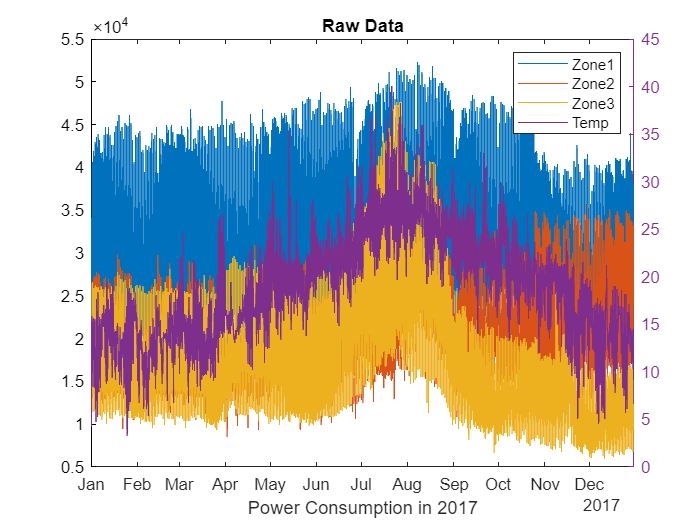

clf
plot(TetuanCitypowerconsumption.DateTime, TetuanCitypowerconsumption.Zone1PowerConsumption)
hold on
plot(TetuanCitypowerconsumption.DateTime, TetuanCitypowerconsumption.Zone2PowerConsumption)
plot(TetuanCitypowerconsumption.DateTime, TetuanCitypowerconsumption.Zone3PowerConsumption)
yyaxis right
plot(TetuanCitypowerconsumption.DateTime, TetuanCitypowerconsumption.Temperature)
hold off
xlabel("Power Consumption in 2017")
title("Raw Data")
% title("Cleaned Data vs Original Data, Correlation coefficient="+correlation_coefficient(1,2))
xlim tight
legend("Zone1", "Zone2", "Zone3", "Temp")

#### Smoothing Raw Data

As can be seen in the above plot the movement of plots is so dense that it is hard to explore the data for long term patterns unless smoothing is applied. 

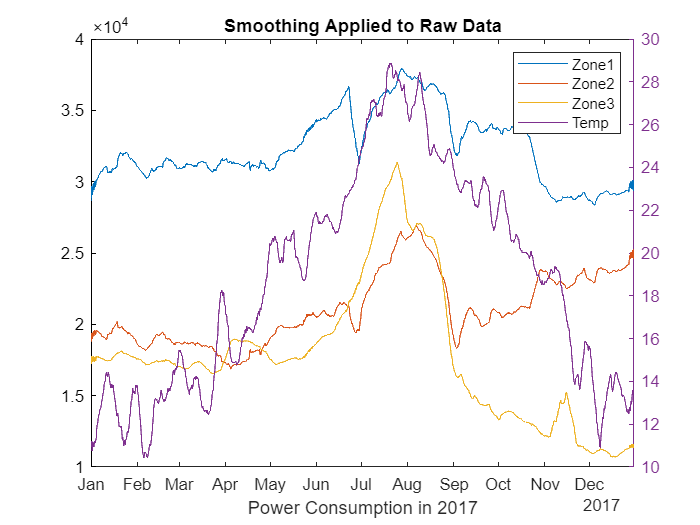

% Smooth input data
clf
TetuanCitypowerconsumption = smoothdata(TetuanCitypowerconsumption2017,"movmean",1008,"DataVariables",["Zone1PowerConsumption","Zone2PowerConsumption","Zone3PowerConsumption","Temperature"]);
plot(TetuanCitypowerconsumption.DateTime, TetuanCitypowerconsumption.Zone1PowerConsumption)
hold on
plot(TetuanCitypowerconsumption.DateTime, TetuanCitypowerconsumption.Zone2PowerConsumption)
plot(TetuanCitypowerconsumption.DateTime, TetuanCitypowerconsumption.Zone3PowerConsumption)
yyaxis right
plot(TetuanCitypowerconsumption.DateTime, TetuanCitypowerconsumption.Temperature)
hold off
xlabel("Power Consumption in 2017")
title("Smoothing Applied to Raw Data")
legend("Zone1", "Zone2", "Zone3", "Temp")
xlim tight

# Reflection

The steps taken as part of the preprocessing of dataset having messy format, missing values and outliers would have made the further processing of data much easier. The subsequent data analysis steps can now be applied on the cleaned data without the fear of issues in the data impacting the reliability of the analysis. All in all, the exercise was a good introduction to the data set and the world of smart grid data analytics.